% Square Sliding on a Frictionless Surface
% Author: aditya-an1l
% Repository : https://github.com/aditya-an1l/sliding_box_matlab
%
% Description: 
%   There are three files in the repository apart from the ReadMe.md 
%   - White Background (Analysis Mode), and 
%   - Gradient Background (Cool Mode), and
%   - Sliding Box Animation 
%   White background mode is good for study pupose, since it allows you
%   conduct your analysis. Meanwhile, Gradient mode is good for a cool
%   preview (hence the name `cool mode`). 
%   Sliding Box Animation is a live script that contains both
%   of the above mentioned codes.
%
%   Sliding Box Animation is recommended - due to more interactive and
%   study options
%
%
% Instruction: 
%    1. Open Matlab (online or offline)
%    2. Create a new Live Script (better than simple script...more interactive options)
%    3. Paste the code into the script
%    4. Run Section / Run
%    5. Change the properties in the parameters


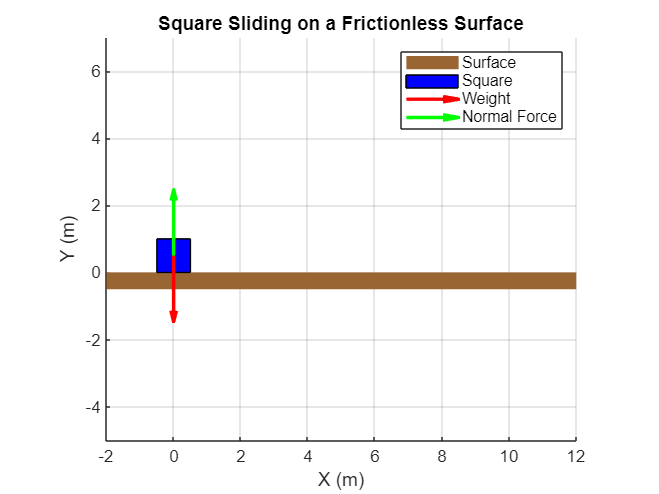

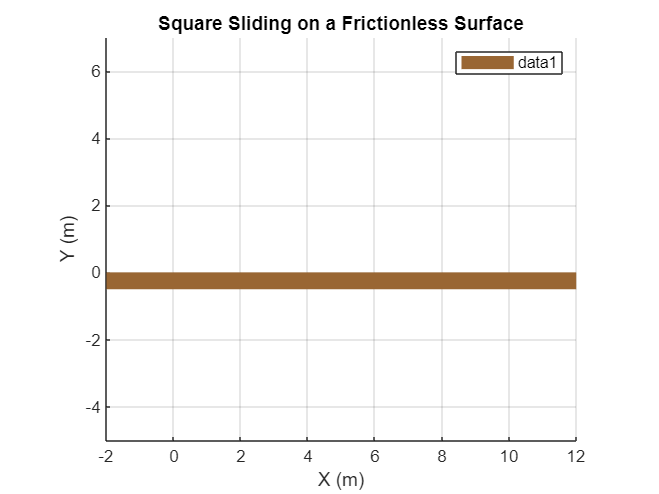

% White Background (analysis mode)

clc
clear all
close all

% Parameters 
% (these are the main physical properties of the object)

side_length = 1;              % Length of the square's side
initial_position = [0, 0.5];  % Starting position (x, y) 
velocity = [1, 0];            % Velocity (x, y)
mass = 1;                     % Mass of the square (kg)
g = 9.81;                     % Acceleration due to gravity (m/s^2)
time_step = 0.1;              % Time step for the animation
simulation_time = 10;         % Total simulation time (s)
arrow_length = 0.2;           % the arrow length (m)


weight = [0, -mass * g];       % Gravitational force (downward)
normal_force = [0, mass * g];  % Normal force (upward)

% Animation setup
figure;
hold on;
axis equal;
axis([-2, 12, -5, 7]);
grid on;
title('Square Sliding on a Frictionless Surface');
xlabel('X (m)');
ylabel('Y (m)');

% Draw the base surface (the brown rectangle)
surface_x = [-2, 12, 12, -2];
surface_y = [0, 0, -0.5, -0.5];
fill(surface_x, surface_y, [0.6, 0.4, 0.2], 'EdgeColor', 'none');  % Brown surface

% Create the square (the main body)
square_x = [-1, 1, 1, -1, -1] * side_length / 2;
square_y = [-1, -1, 1, 1, -1] * side_length / 2;

% Animation loop 
for t = 0:time_step:simulation_time

    position = initial_position + velocity * t;
    
    % Plot the square
    fill(position(1) + square_x, position(2) + square_y, 'b', 'DisplayName', 'Square');
    
 
    scaling_factor = arrow_length;  % Adjust this value to control arrow length
    scaled_weight = weight * scaling_factor;
    scaled_normal_force = normal_force * scaling_factor;

    % Use the scaled forces in the quiver function
    quiver(position(1), position(2), scaled_weight(1), scaled_weight(2), 0, 'r', ...
    'LineWidth', 2, 'MaxHeadSize', 0.5, 'AutoScale', 'off');
    quiver(position(1), position(2), scaled_normal_force(1), scaled_normal_force(2), 0, 'g', ...
    'LineWidth', 2, 'MaxHeadSize', 0.5, 'AutoScale', 'off');

    
    legend('Surface', 'Square', 'Weight', 'Normal Force', 'Location', 'northeast');
    drawnow;
    
    
    pause(time_step);
    
    % Clear the plot for the next frame
    cla;
    
    % Redraw the surface for the next frame
    fill(surface_x, surface_y, [0.6, 0.4, 0.2], 'EdgeColor', 'none');  % Brown surface
end

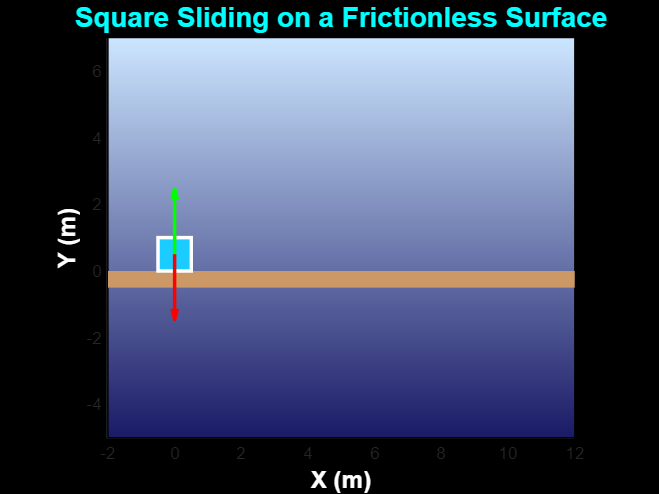

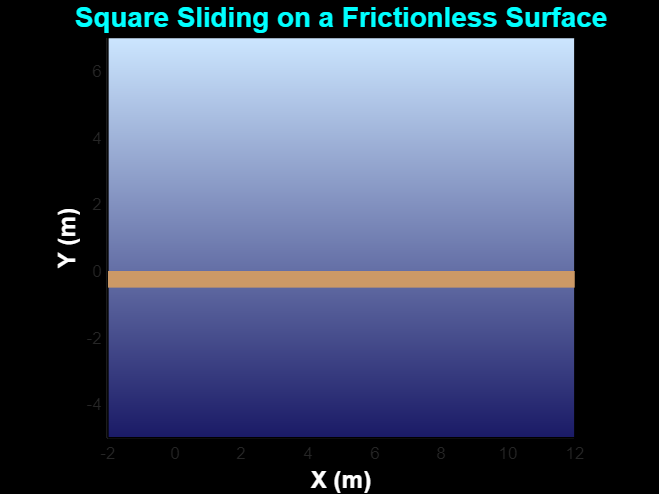

% Gradient Background (cool mode 😉 )

clc
clear all 
close all

% Parameters 
% (these are the main physical properties of the object)

side_length = 1;              % Length of the square's side
initial_position = [0, 0.5];  % Starting position (x, y) 
velocity = [1, 0];            % Velocity (x, y)
mass = 1;                     % Mass of the square (kg)
g = 9.81;                     % Acceleration due to gravity (m/s^2)
time_step = 0.1;              % Time step for the animation
simulation_time = 10;         % Total simulation time (s)
arrow_length = 0.2;           % the arrow length (m)

weight = [0, -mass * g];       % Gravitational force (downward)
normal_force = [0, mass * g];  % Normal force (upward)

% Gradient background colors
background_color1 = [0.1, 0.1, 0.4];  % Dark blue
background_color2 = [0.8, 0.9, 1];    % Light blue

% Animation setup
figure('Color', 'k');
hold on;
axis equal;
axis([-2, 12, -5, 7]);
set(gca, 'Color', 'none'); % Set axes to transparent for gradient

% Add gradient background
f = fill([-2, 12, 12, -2], [-5, -5, 7, 7], 'w');
uistack(f, 'bottom');
set(f, 'FaceColor', 'interp', ...
       'FaceVertexCData', [background_color1; background_color1; background_color2; background_color2]);

grid on;
set(gca, 'GridColor', [0.5, 0.5, 0.5], 'GridAlpha', 0.3);
xlabel('X (m)', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'w');
ylabel('Y (m)', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'w');
title('Square Sliding on a Frictionless Surface', ...
    'FontSize', 16, 'FontWeight', 'bold', 'Color', 'c');

surface_x = [-2, 12, 12, -2];
surface_y = [0, 0, -0.5, -0.5];
fill(surface_x, surface_y, [0.8, 0.6, 0.4], 'EdgeColor', 'none');  % brown surface

% Create the square
square_x = [-1, 1, 1, -1, -1] * side_length / 2;
square_y = [-1, -1, 1, 1, -1] * side_length / 2;

% Animation loop
for t = 0:time_step:simulation_time
    position = initial_position + velocity * t;
    
    fill(position(1) + square_x, position(2) + square_y, ...
        [0.1, 0.8, 1], 'EdgeColor', 'w', 'LineWidth', 2);
    
    scaling_factor = arrow_length;  % Adjust this value to control arrow length
    scaled_weight = weight * scaling_factor;
    scaled_normal_force = normal_force * scaling_factor;

    % Use the scaled forces in the quiver function
    quiver(position(1), position(2), scaled_weight(1), scaled_weight(2), 0, 'r', ...
    'LineWidth', 2, 'MaxHeadSize', 0.5, 'AutoScale', 'off');
    quiver(position(1), position(2), scaled_normal_force(1), scaled_normal_force(2), 0, 'g', ...
    'LineWidth', 2, 'MaxHeadSize', 0.5, 'AutoScale', 'off');
    
    drawnow;
    
    pause(time_step);
    
    % Clear the plot for the next frame
    cla;
    
    % Redraw the gradient background and surface
    fill([-2, 12, 12, -2], [-5, -5, 7, 7], 'w', 'FaceColor', 'interp', ...
        'FaceVertexCData', [background_color1; background_color1; background_color2; background_color2]);
    fill(surface_x, surface_y, [0.8, 0.6, 0.4], 'EdgeColor', 'none');  % brown surface
end